# ELABORATO 2 -  PRODOTTO MATRICE VETTORE PER RIGHE

# LO BRUTTO FABIO / MAIONE PAOLO

## DEFINIZIONE DEL PROBLEMA

Si vuole progettare un algoritmo in MPI per risolvere il prodotto vettoriale tra una matrice, di dimensioni M*N, e un vettore di reali, di dimensione N, su p processori.

In particolare si utilizza l'infrastruttura S.C.o.P.E. per permettere l'esecuzione del software in un ambiente parallelo.

## DESCRIZIONE DELL'ALGORITMO

In particolare le fasi dell'algoritmo, implementato nel file `elaborato_2.c`, sono:

1) Distribuzione per righe della matrice in p processori e distribuzione del vettore: ognuno dei p processori eseguirà il prodotto vettoriale tra la porzione di matrice ricevuta dal processo *root*, cioè quello con rank 0, e il vettore;

2) Elaborazione del prodotto vettoriale in parallelo ;

3) Aggregazione del vettore calcolata nel processo *root* che determinerà il risultato finale.

A tal proposito sono state utilizzate le primitive fornite da MPI (rispettivamente per la prima fase `MPI_Scatterv()` e per la terza `MPI_Gatherv()`).

Inoltre l'algoritmo progettato comprende anche il caso in cui la dimensione M (cioè il numero di righe della matrice) non sia multipla del numero di processori p a disposizione.

Si è scelto di misurare i tempi di esecuzione nel processo di rank 0 usando la primitiva` MPI_Wtime()` tra la fase 2 e la fase 3 scegliendo il minimo tra 3 misurazioni ripetute.

Infine, si osservi che i controlli di robustezza del software sono stati interamente delegati al processo *root*.

## INPUT, OUTPUT E CONDIZIONI DI ERRORE

- **Input**: la matrice e il vettore di cui effettuare il prodotto vettoriale, le loro dimensioni.

- **Output**: il vettore che rappresenta il prodotto vettoriale tra la matrice e il vettore.

- **Condizioni di errore**: la dimensione delle righe della matrice eve essere uguale al numero di colonne del vettore e devono essere interi positivi. Il numero di righe della matrice non deve essere minore del numero di processori.

## ESEMPIO DI FUNZIONAMENTO

Nell'immagine seguente vi è un esempio di funzionamento, con 4 processori, matrice di dimensione ${10}^5$ * ${10}^3$ e dimensione dei vettori pari a ${10}^3$ .

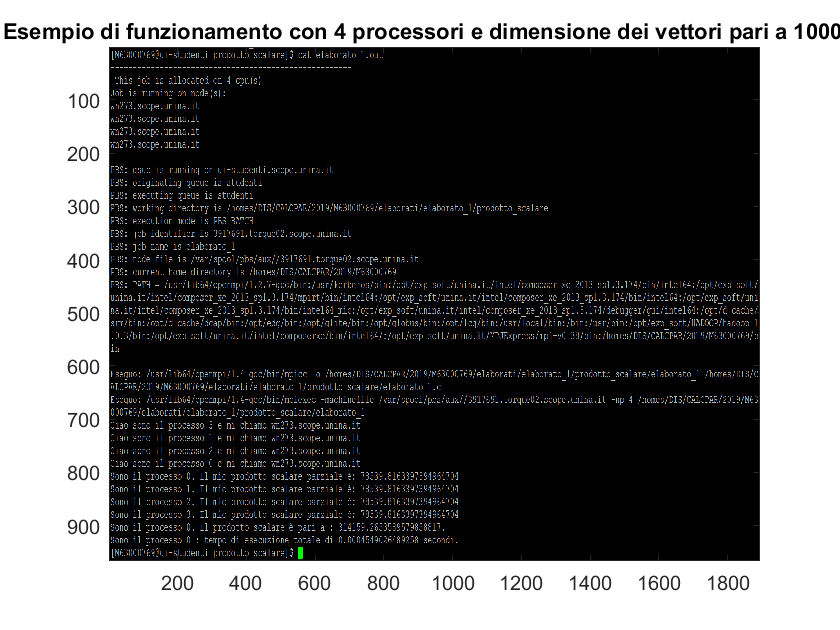

%esempio di funzionamento
funzionamento

## ESEMPI DI ERRORE

Nelle successivi immagini, invece, sono mostrati i messaggi di errore al verificarsi delle condizioni sopra citate.

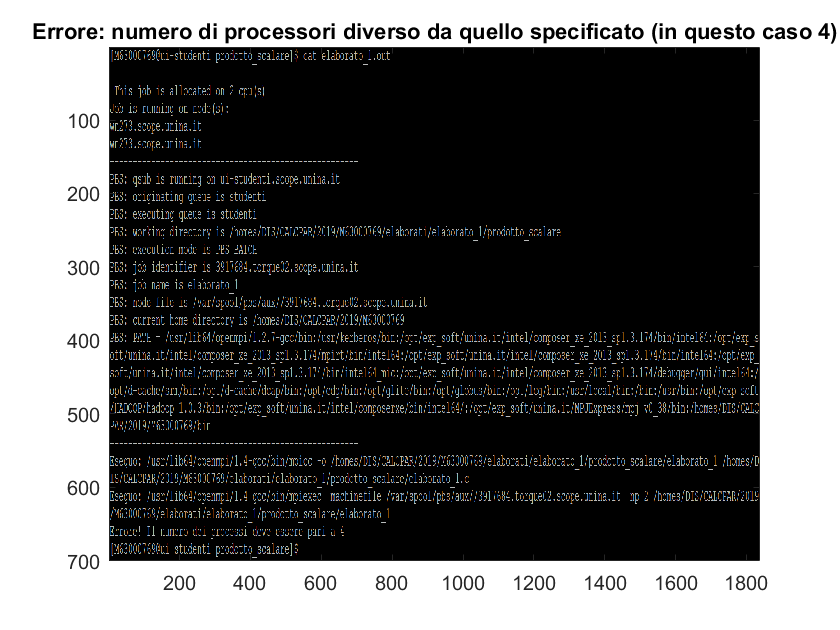

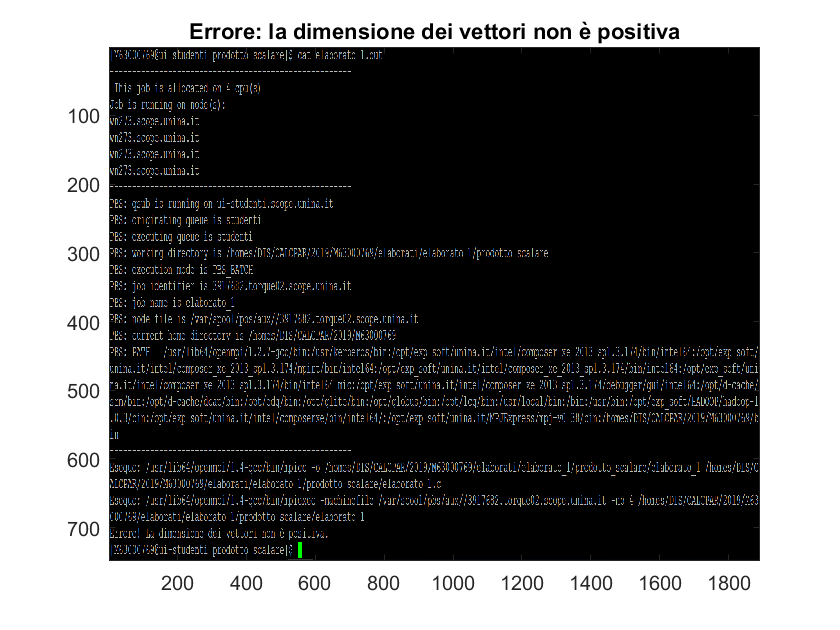

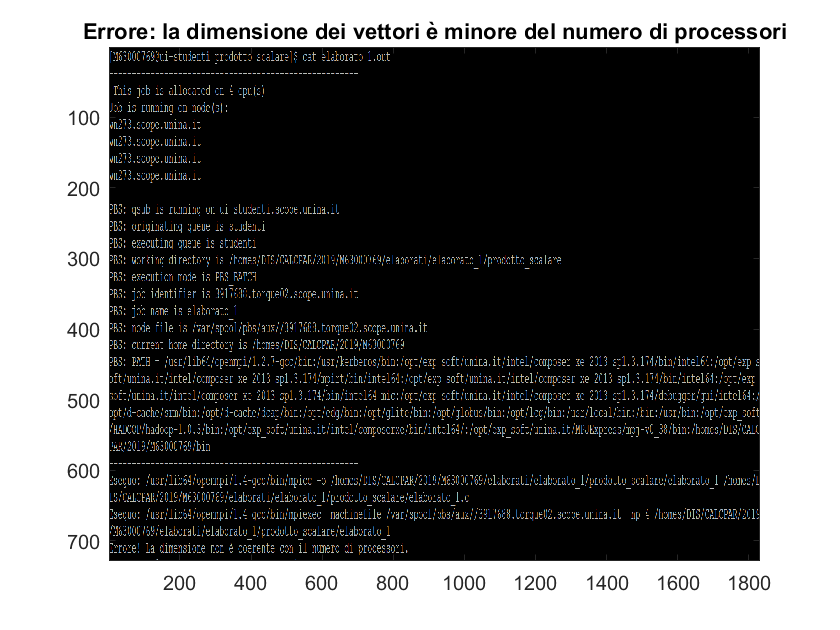

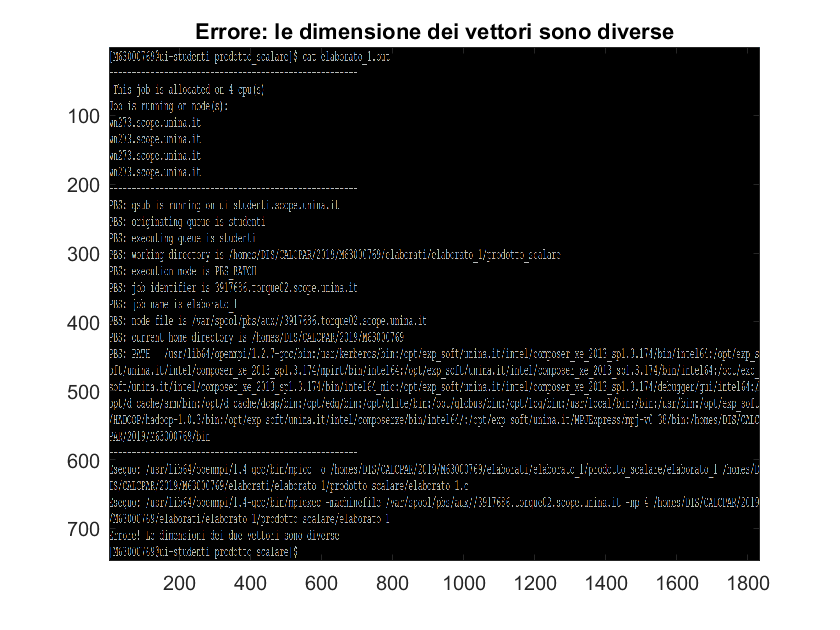

%un esempio per ciascuna condizione di errore
errori

## ANALISI DELLE PRESTAZIONI (T(p), S(p), E(p))

## Tempo di esecuzione - T(p)

Si è scelto di misurare i tempi di esecuzione nel processo* root* usando la primitiva `MPI_Wtime()`. In particolare l'intervallo di tempo misurato è quello che comprende le fasi 2 e 3 dell'algoritmo prima citate.

Per ciascuna misurazione (al variare di N da 10k a 100M e al variare di p da 2 a 16) è stato considerato il minimo tra 3 esecuzioni ripetute, eseguite in momenti diversi.

Di seguito si riportano i risultati in forma di tabelle e grafici.

%esecuzione script per tabelle e grafici
tempi

Undefined function or variable 'tempi'.

L'ultimo grafico è quello che riassume i risultati ottenuti per tutti i possibili valori di N e p. Sono forniti due ulteriori grafici (i primi due) che mostrano gli andamenti più nel dettaglio.

Tali risultati verificano la legge di Amdahl: all'aumentare del numero di processori, fissata la dimensione del problema (N), i tempi peggiorano (cioè aumentano). Per esempio, si osservi il comportamento nel caso di N = ${10}^6$ nel grafico "Analisi dettagliata da 10k a 1M".  Inoltre è verificata anche la legge di Gustafson in quanto all'aumentare sia di N che di p, il tempo di esecuzione migliora (cioè diminuisce) come è evidente nel grafico "Analisi complessiva".

## Speed up ed Efficienza - S(p) ed E(p)

Si è calcolato, inoltre, il tempo di riferimento T(1) che corrisponde al tempo di esecuzione su un unico processore.

A partire dai tempi misurati nella sezione precedente e da T(1) è stato calcolato lo speed-up al variare di N e p.

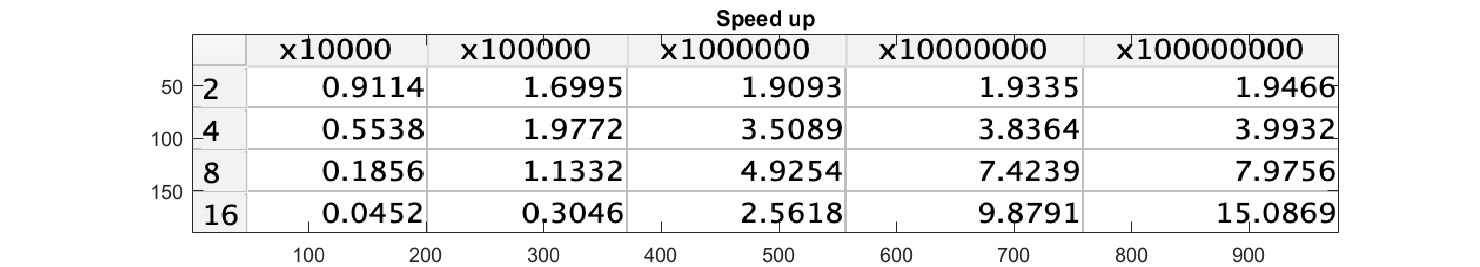

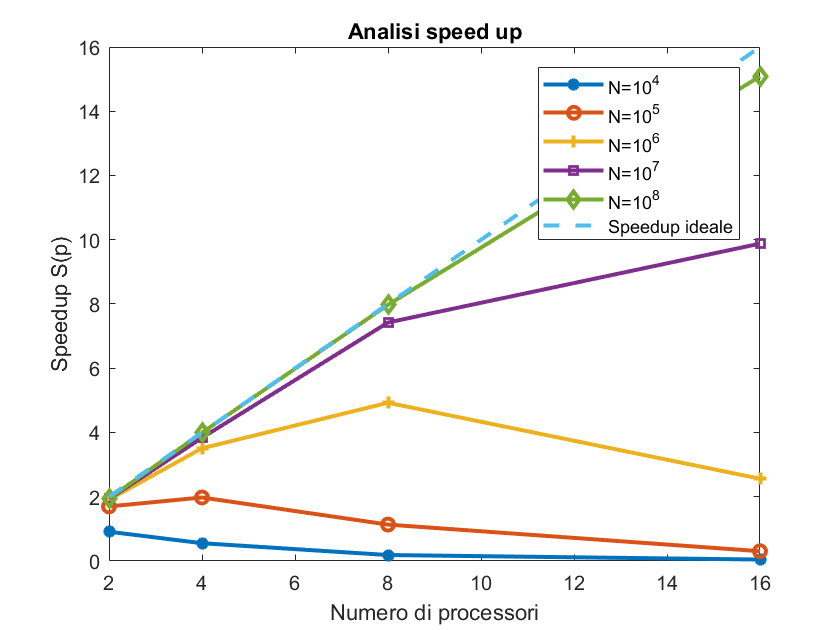

%esecuzione script per tabelle e grafici
speedup

Infine si è calcolata l'efficienza rapportando lo speed-up S(p) al numero di processori p.

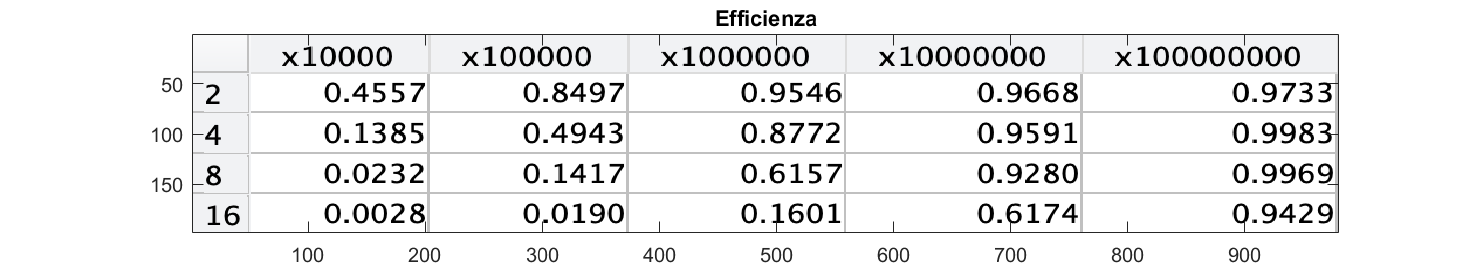

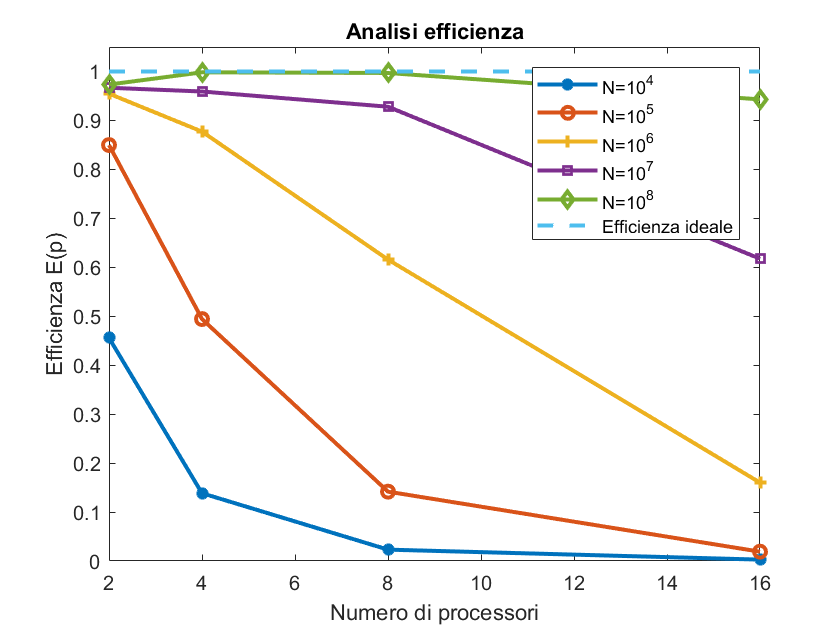

%esecuzione script per tabelle e grafici
efficienza

## Conclusioni

Dai grafici appena presentati si possono trarre alcune considerazioni.

Analizzando l'efficienza si nota come nel caso N=${10}^4$ l'efficienza è bassa anche per 2 processori; ciò indica che è un problema che non conviene risolvere in parallelo, fissate queste dimensioni.

Tuttavia anche da N=${10}^5$ fino a N=${10}^7$ si osserva che l'efficienza migliore si ottiene in corrispondenza di soltanto 2 processori.

Si possono ripetere analoghe considerazioni come quelle fatte per i tempi, notando che, per N fissato, l'efficienza peggiora dopo un certo valore di p, e che, in generale, all'aumentare sia di N che di p, l'efficienza migliora.

Solo nel caso in cui N=${10}^8 \text{ }$l'efficienza ottima si ha con p=4 processori.

Analoghe considerazioni per lo speedup.

## ANALISI DELL' ACCURATEZZA

Confrontando il risultato ottenuto sul cluster Scope e quello ottenuto su MATLAB si ottiene il seguente errore relativo, fissando a 8 il numero di processori con dimensione dei vettori pari a ${10}^5$.

%esecuzione script per i test di accuratezza
accuratezza

risultato_scope =      3.141592653589620e+05


risultato_matlab =      3.141592653587123e+05


errore_relativo =      7.946690904462235e-13
